### Parameters for analysis

clear

Parameters for spectral events data:

data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );
task      = '02_Baseline';
band      = 'beta';
method    = 1;
chans     = [36 104]; % list of chans to plot
time_win  = [0 5000]; % time window to use relative to stim onset (ms)
beapp_tag = '_wbadchan_5sec';

Group assignment information:

group_name     = {'TD','ASD','SPD'};
groups_to_plot = 1:3;
grp_table      = fullfile(data_path,'01_Subject_Info_For_Processing','Group_Assignments.mat');

Parameters for plotting:

conds_to_inc = 0; % if a subset, 0 to include all
seg_length   = abs(sum(time_win))/1000;
save_fig     = true;
% fields to extract from spec_events structs
features{1,:} = {'eventnumber','maximapowerFOM','duration','Fspan'};
if seg_length > 0
    features{2,:} = {'Event rate (Hz)','Power (FOM)','Duration (ms)','F-span (Hz)'};
else
    features{2,:} = {'Events per segment','Power (FOM)','Duration (ms)','F-span (Hz)'};
end

 

### Sort spectral events data

%% get information for plotting
colors   = {'#4444c9','#32a852','#db4214'};
markers  = {'.','.','.','+','*'};
time_str = get_time_win_str(time_win);
chan_str = get_chan_str({},chans);
if isempty(chan_str), chan_str = '1020'; end
task_abbrevs = containers.Map({'02_Baseline','stepwise_loudness',  ...
                               'auditory_temporal_habituation', ...
                               'tactile_spatial_suppression',   ...
                               'tactile_temporal_habituation'}, ...
                               {'Resting state','SL','ATH','TSS','TTH'});
task_abb = task_abbrevs(task);

%% load group assignment table 
load(grp_table,'groups')

%% load spectral events data
n_feats = length(features{1});
% average eeg channels first, then run spectral events
load_chans = strrep(int2str(chans),' ','');
if isempty(chans)
    load_chans = '1020';
end
% load channel SET data
tag = [band '_' int2str(method) '_' load_chans beapp_tag];
load(fullfile(data_path,task,'spec_events',[tag '.mat']),'spec_events');
% sort data by group
sorted_eeg = sort_data_by_group_SET(spec_events,groups,group_name);
clear spec_events

% get subject means and standard deviations
[~,~,s_all] = subj_avg_spec_events(sorted_eeg,features{1},conds_to_inc);

### Plot individual distributions

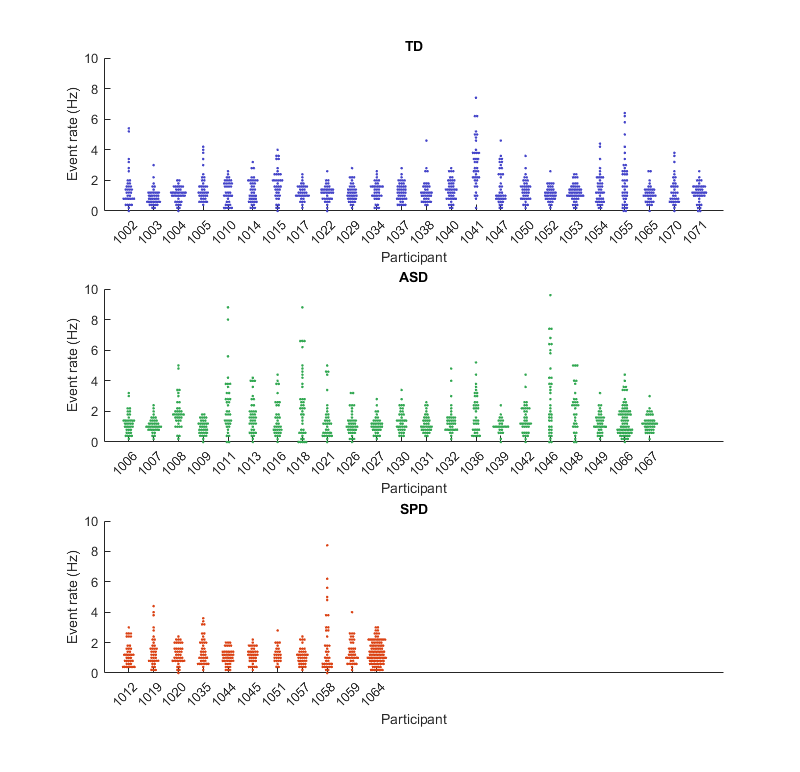

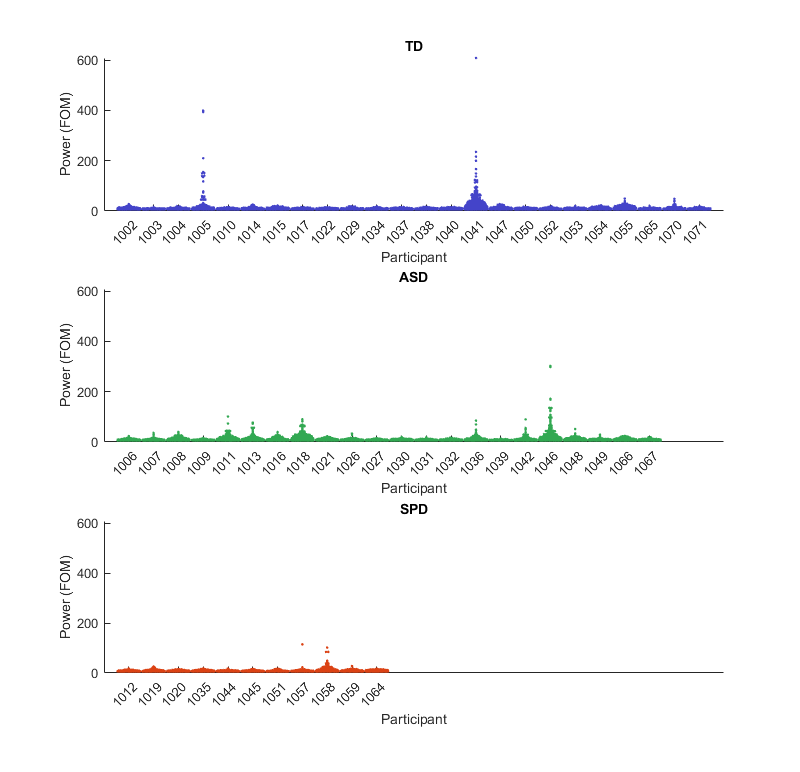

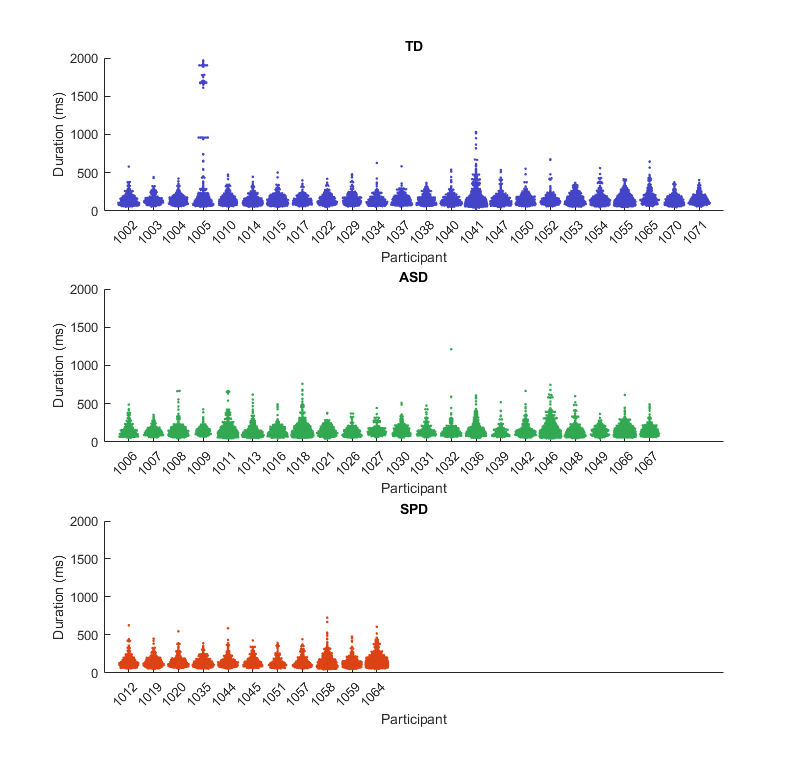

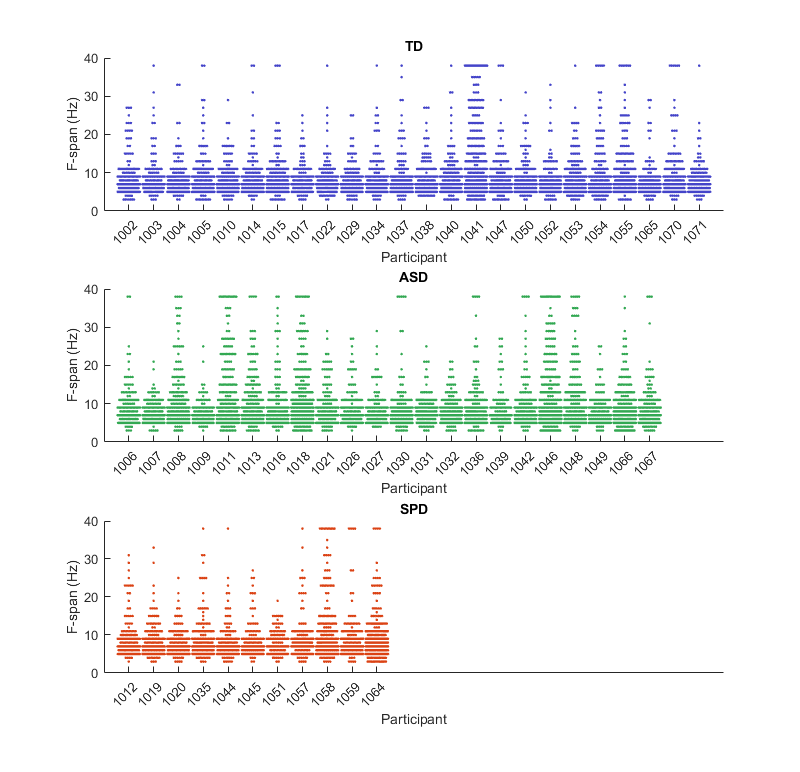

% iterate through features
for i_f = 1:n_feats
    feat = features{1}{i_f};
    f = figure('Position',[50 50 1000 800]);
    % iterate through groups
    for i_g = groups_to_plot
        % get group information
        group = group_name{i_g};
        ids   = s_all(1).(group).id;
        group_feats = s_all(1).(group).(feat)(:);
        % convert event number to event rate
        if strcmp(feat,features{1}{1})
            group_feats = cellfun(@(x) x/seg_length,group_feats,'UniformOutput',false);
        end
        % plot group spreads
        ax(i_g) = subplot(length(groups_to_plot),1,i_g);
        plotSpread(group_feats,'distributionColors',colors{i_g},'distributionMarkers',markers{i_g})
        title(group)
        xlabel('Participant'), ylabel(features{2}{i_f})
        xticklabels(ids), xtickangle(45)
    end
    linkaxes(ax,'xy')

    % save figure
    if save_fig
        pause(0.2)
        fig_path = fullfile(data_path,task,'figures','spec_events','indiv_dists');
        if ~exist(fig_path,'dir'), mkdir(fig_path); end
        fig_fname = [band '_' chan_str '_' feat];
        fig_fname = fullfile(fig_path,fig_fname);
        saveas(f,fig_fname,'jpg')
    end
end